% Pre-defined
N1 = 15;
N2 = 33;
N = N2;
omegaC = pi/4;
hanning = 'hn';
hamming = 'hm';
rect = 'r'; % Do nothing(Because it's already fixed to N point)
triang = 'tr'

triang = 'tr'

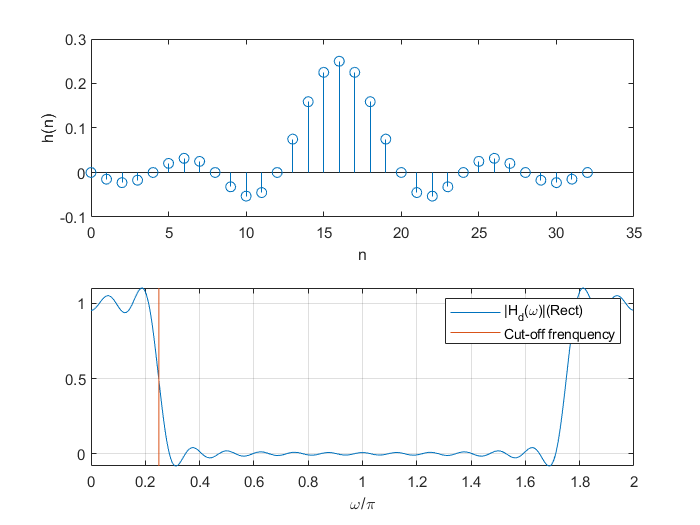

win_type = hamming; % Choose one type (DEFAULT: hanning)

bianer = 3;
M = 2^ceil(log2(N)+bianer);
n = 0:N-1;

[hd, tau] = ideallp(omegaC, N);

[hdw, w, ~] = amplres(hd, M);

figure 
subplot(2, 1, 1)
stem(n, hd)
xlabel('n')
ylabel('h(n)')

subplot(2, 1, 2)
plot(w/pi, hdw)

grid on

hold on
plot([omegaC/pi omegaC/pi], ylim)
hold off
xlabel('\omega/\pi')

legend('|H_d(\omega)|(Rect)', 'Cut-off frenquency')

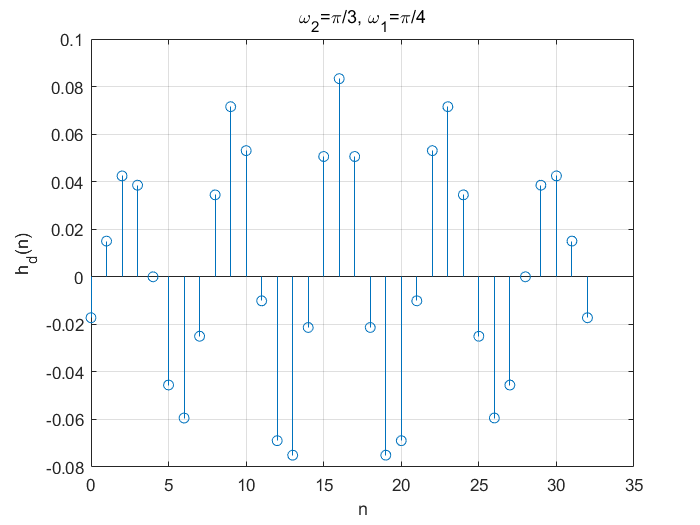

x_bp = ideallp(pi/3, N2) - ideallp(pi/4, N2);
figure
stem(0:N2-1, x_bp);
grid on
xlabel('n')
ylabel('h_d(n)')
title('\omega_2=\pi/3, \omega_1=\pi/4')

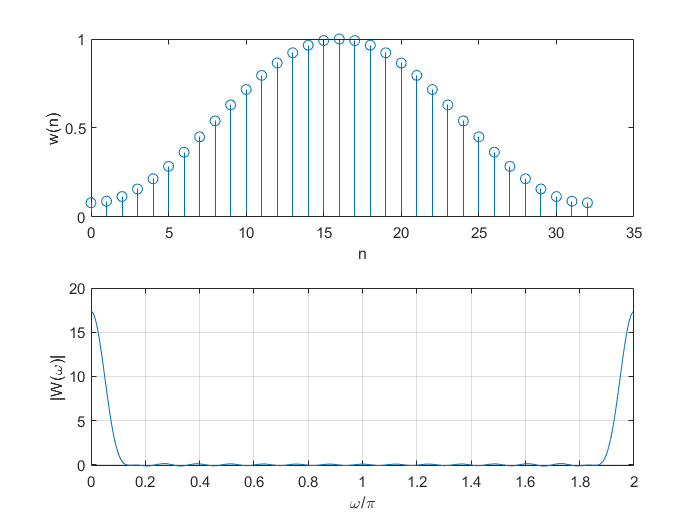

% Get window
wn = choose_win_type(win_type, N)';
[Hww, w, ~] = amplres(wn, M);

figure
subplot(2, 1, 1)
stem(n, wn)
xlabel('n')
ylabel('w(n)')

subplot(2, 1, 2)
plot(w/pi, Hww)

grid on

xlabel('\omega/\pi')
ylabel('|W(\omega)|')

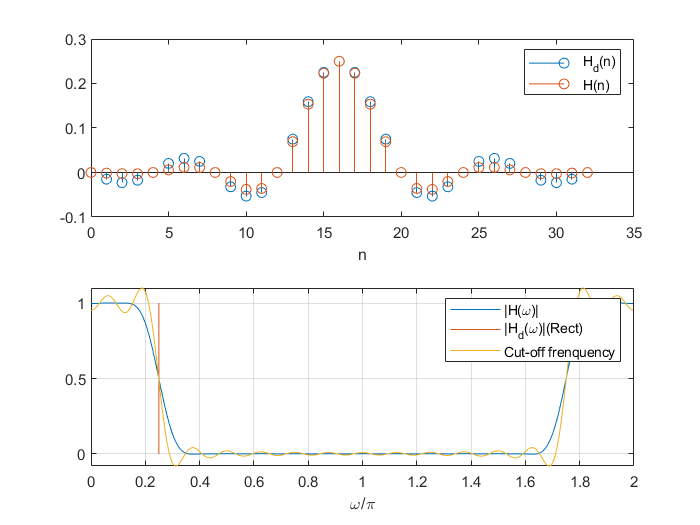

% Get -h 
h = wn.*hd; % Get your window


[hw, w, ~] = amplres(h, M);

figure
subplot(2, 1, 1)
stem(n, hd)

hold on
stem(n, h)
hold off

xlabel('n')

legend('H_d(n)', 'H(n)')

subplot(2, 1, 2)
plot(w/pi, hw)

grid on

hold on
plot([omegaC/pi omegaC/pi], ylim)
plot(w/pi, hdw)
hold off

xlabel('\omega/\pi')

legend('|H(\omega)|', '|H_d(\omega)|(Rect)', 'Cut-off frenquency')

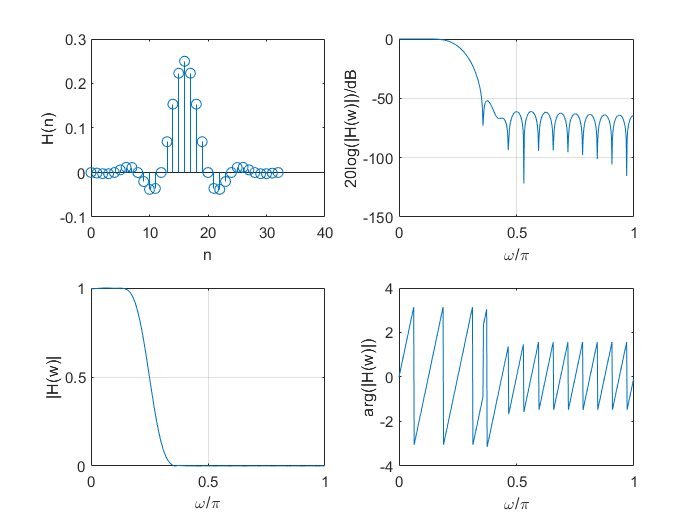

[db, mag, pha, grd, w] = freqz_m(h, [1], M);
    
figure 
subplot(2, 2, 1)
stem(n, h)
xlabel('n')
ylabel('H(n)')

subplot(2, 2, 2)
plot(w/pi, db)
grid on 
xlabel('\omega/\pi');
ylabel('20log(|H(w)|)/dB')

subplot(2, 2, 3)
plot(w/pi, mag)
grid on
xlabel('\omega/\pi')
ylabel('|H(w)|')

subplot(2, 2, 4)
plot(w/pi, pha)
xlabel('\omega/\pi')
ylabel('arg(|H(w)|)')

function [hd, tau] = ideallp(wc, N)
% Ideal low-pass digital filter(with cut-off angular frenquency wc)
    tau = (N-1)/2;
    n = 0:N-1;
    m = n - tau + eps; % Avoid ZeroDivision Error
    hd = sin(wc * m)./(pi * m);
end

function [Hw, w, type] = amplres(h, M)
    
    N = length(h);
    L = floor((N-1)/2);
    h = h(:)';
    
    n = 1:L+1;
    w = (0:M)* 2 *pi /(M+1);
    
    if all(abs(h(n) - h(N - n + 1))<1e-10)
        % Class I(Type I or Type II)
        Hw = 2 * h(n) * cos(((N+1)/2 - n)' * w) - mod(N, 2) * h(L+1);
        type = 2 - mod(N, 2); %N - Even, type->2, N - Odd, type -> 1.
    elseif all(abs(h(n) - h(N - n + 1))<1e-10)&&(h(L+1) * mod(N, 2) == 0)
        Hw = 2 * h(n) * sin(((N+1)/2 - n)' * w);
        type = 4 - mod(N, 2); %N - Even, type->4, N - Odd, type -> 3.
        
    else error('Not a linear phase FIR filter');
    end
end

function w = choose_win_type(win_type, N)
    switch win_type
        case 'hn'
            w = hanning(N);
        case 'hm'
            w = hamming(N);
        case 'r'
            w = rectwin(N);
        case 'tr'
            w = triang(N);
    end
end

function [db, mag, pha, grd, w] = freqz_m(b, a, M)
    [H, w] = freqz(b, a, M*2, 'whole');
    H = H(1:M)'; w = w(1:M)';
    mag = abs(H);
    db = 20*log10((mag+eps)/max(mag));
    pha = angle(H);
    grd = grpdelay(b, a, w);
    
end